clc; clear; close all;

% Cargar datos
data = readtable('Five_times_Kinematics_HT_Query_MATLAB_SIN_OUTLIERS.xlsx');


fprintf('Dimensiones del dataset: %d filas x %d columnas\n', size(data,1), size(data,2));

Dimensiones del dataset: 46 filas x 87 columnas


disp('Variables del dataset:');

Variables del dataset:


disp(data.Properties.VariableNames);

    {'reclutado'}    {'GroupName'}    {'x1_AAFEM'}    {'x2_AAFEM'}    {'x3_AAFEM'}    {'x4_AAFEM'}    {'x5_AAFEM'}    {'x1_AAIEM'}    {'x2_AAIEM'}    {'x3_AAIEM'}    {'x4_AAIEM'}    {'x5_AAIEM'}    {'x1_AKFEM'}    {'x2_AKFEM'}    {'x3_AKFEM'}    {'x4_AKFEM'}    {'x5_AKFEM'}    {'x1_AKAAM'}    {'x2_AKAAM'}    {'x3_AKAAM'}    {'x4_AKAAM'}    {'x5_AKAAM'}    {'x1_AKIEM'}    {'x2_AKIEM'}    {'x3_AKIEM'}    {'x4_AKIEM'}    {'x5_AKIEM'}    {'x1_AHPFEM'}    {'x2_AHPFEM'}    {'x3_AHPFEM'}    {'x4_AHPFEM'}    {'x5_AHPFEM'}    {'x1_AHPAAM'}    {'x2_AHPAAM'}    {'x3_AHPAAM'}    {'x4_AHPAAM'}    {'x5_AHPAAM'}    {'x1_AHPIEM'}    {'x2_AHPIEM'}    {'x3_AHPIEM'}    {'x4_AHPIEM'}    {'x5_AHPIEM'}    {'x1_APTILTM'}    {'x2_APTILTM'}    {'x3_APTILTM'}    {'x4_APTILTM'}    {'x5_APTILTM'}    {'x1_APOBLIM'}    {'x2_APOBLIM'}    {'x3_APOBLIM'}    {'x4_APOBLIM'}    {'x5_APOBLIM'}    {'x1_APROTM'}    {'x2_APROTM'}    {'x3_APROTM'}    {'x4_APROTM'}    {'x5_APROTM'}    {'x1_ASPMLM'}    {'x2_ASPMLM'}    {'x3_ASP


% Seleccionar columnas numéricas
isNum = varfun(@isnumeric, data, 'OutputFormat','uniform');
numericData = data(:, isNum);
X = table2array(numericData);
[n, p] = size(X);
fprintf('El dataset sin outliers tiene %d muestras y %d dimensiones.\n', n, p);

El dataset sin outliers tiene 46 muestras y 87 dimensiones.



% Inicializar lista para guardar R²
R2_values = zeros(p, 1);
varNames = numericData.Properties.VariableNames;

% Evaluación de normalidad univariada con QQ-plot
fprintf('\nEvaluación de normalidad con QQ-plot y R²:\n');


Evaluación de normalidad con QQ-plot y R²:


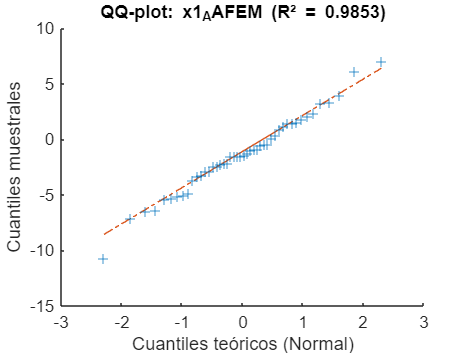

Variable "x1_AAFEM": R² = 0.9853


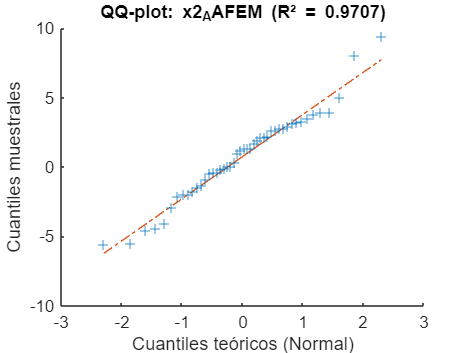

Variable "x2_AAFEM": R² = 0.9707


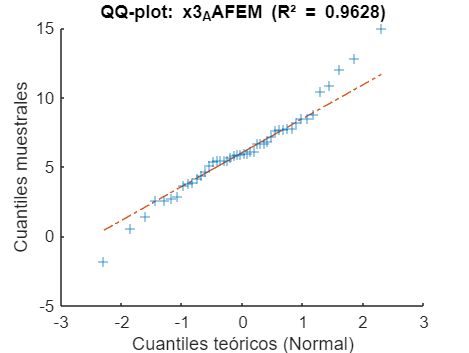

Variable "x3_AAFEM": R² = 0.9628


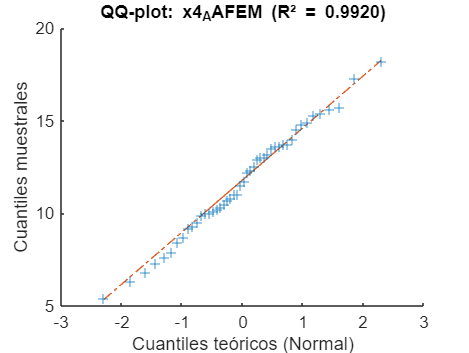

Variable "x4_AAFEM": R² = 0.9920


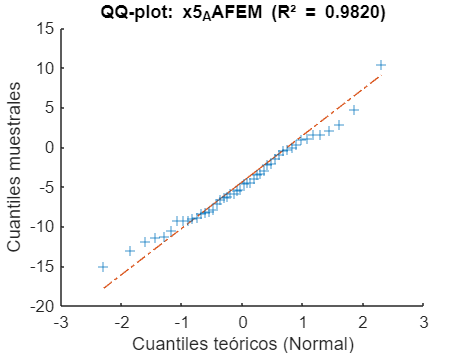

Variable "x5_AAFEM": R² = 0.9820


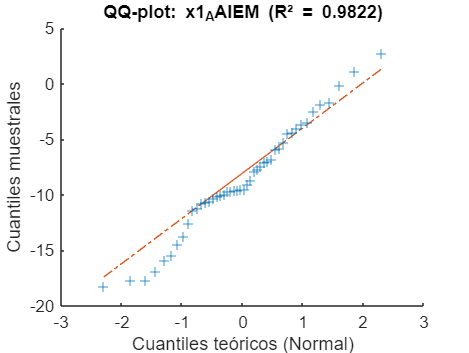

Variable "x1_AAIEM": R² = 0.9822


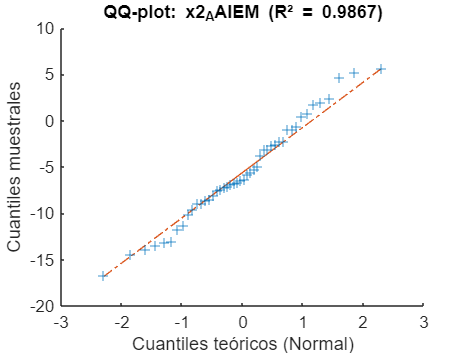

Variable "x2_AAIEM": R² = 0.9867


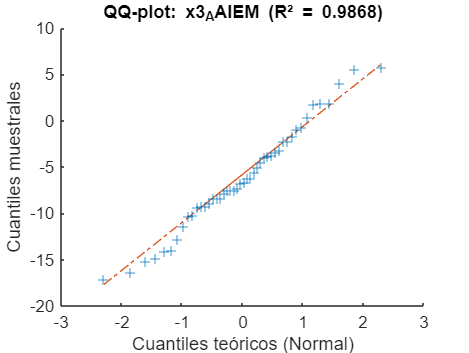

Variable "x3_AAIEM": R² = 0.9868


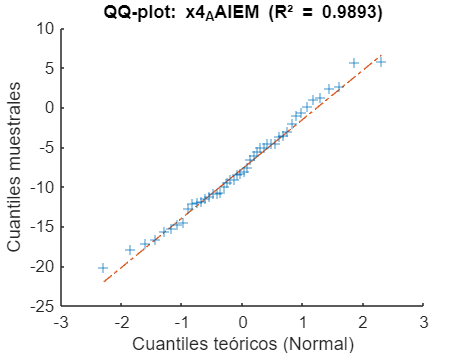

Variable "x4_AAIEM": R² = 0.9893


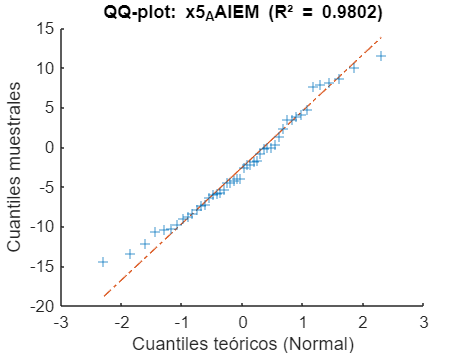

Variable "x5_AAIEM": R² = 0.9802


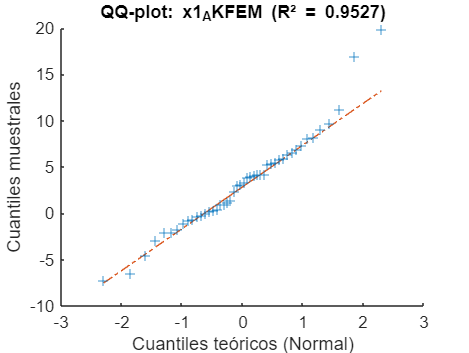

Variable "x1_AKFEM": R² = 0.9527


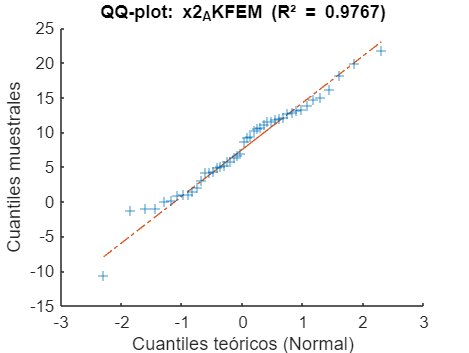

Variable "x2_AKFEM": R² = 0.9767


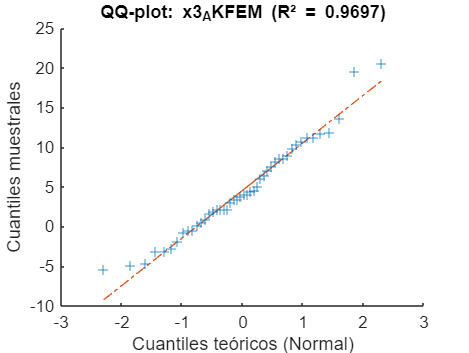

Variable "x3_AKFEM": R² = 0.9697


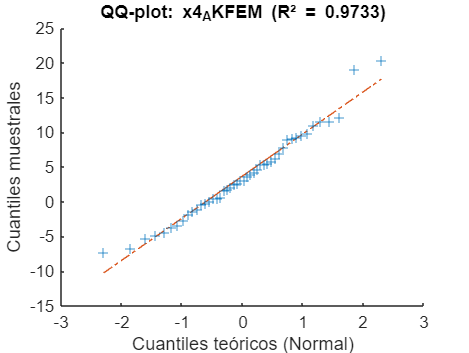

Variable "x4_AKFEM": R² = 0.9733


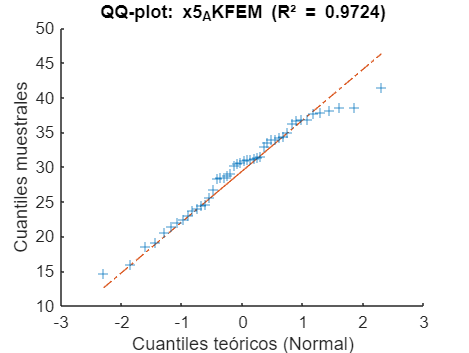

Variable "x5_AKFEM": R² = 0.9724


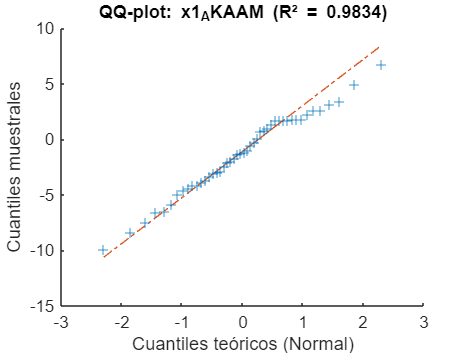

Variable "x1_AKAAM": R² = 0.9834


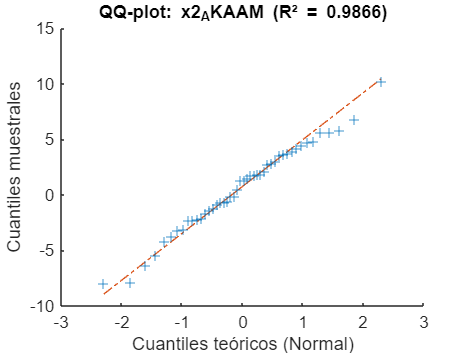

Variable "x2_AKAAM": R² = 0.9866


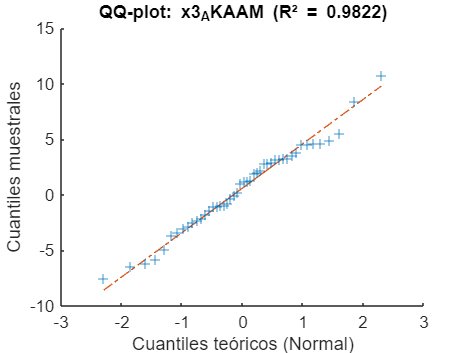

Variable "x3_AKAAM": R² = 0.9822


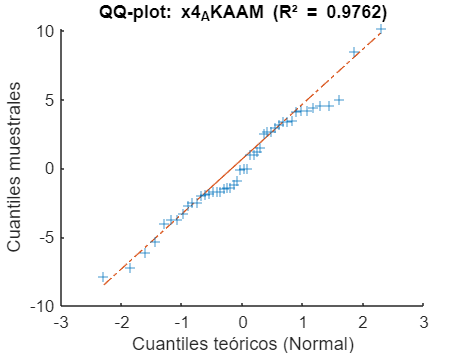

Variable "x4_AKAAM": R² = 0.9762


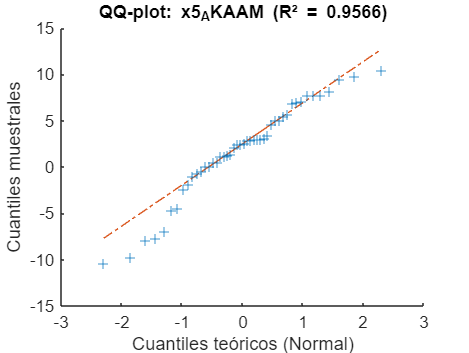

Variable "x5_AKAAM": R² = 0.9566


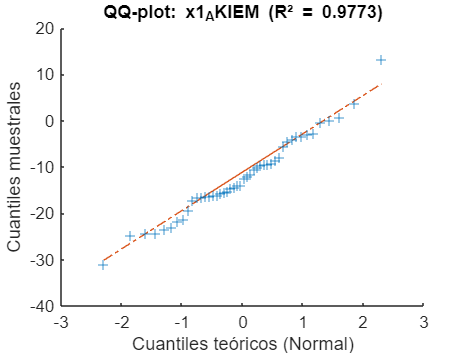

Variable "x1_AKIEM": R² = 0.9773


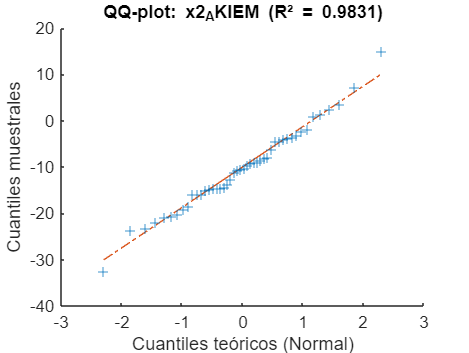

Variable "x2_AKIEM": R² = 0.9831


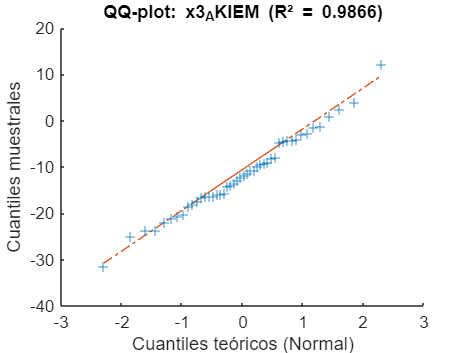

Variable "x3_AKIEM": R² = 0.9866


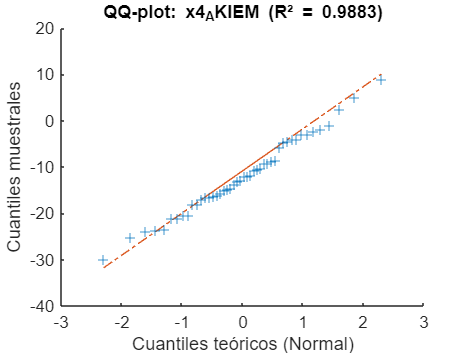

Variable "x4_AKIEM": R² = 0.9883


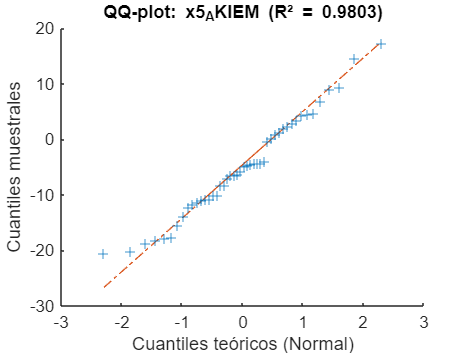

Variable "x5_AKIEM": R² = 0.9803


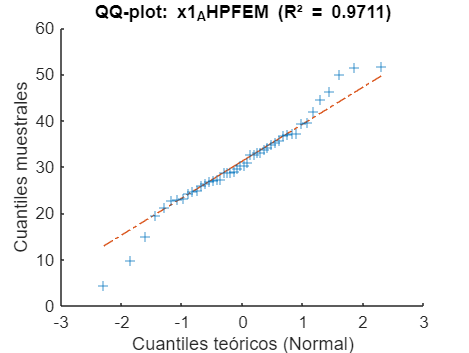

Variable "x1_AHPFEM": R² = 0.9711


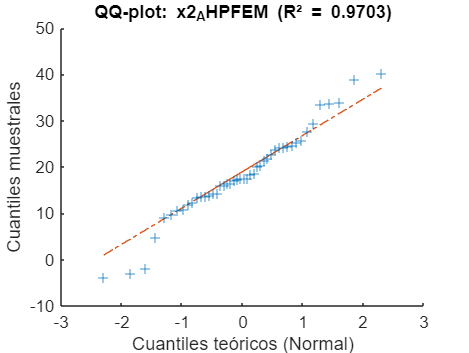

Variable "x2_AHPFEM": R² = 0.9703


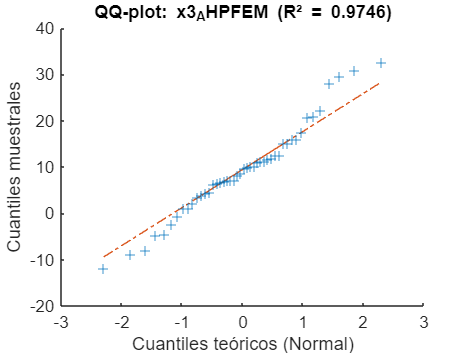

Variable "x3_AHPFEM": R² = 0.9746


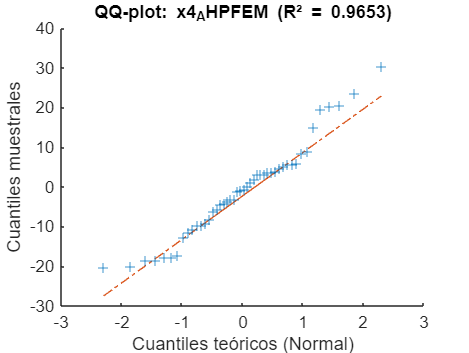

Variable "x4_AHPFEM": R² = 0.9653


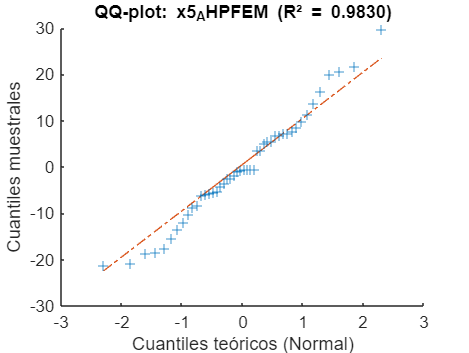

Variable "x5_AHPFEM": R² = 0.9830


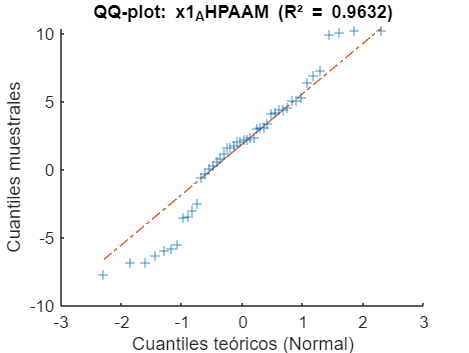

Variable "x1_AHPAAM": R² = 0.9632


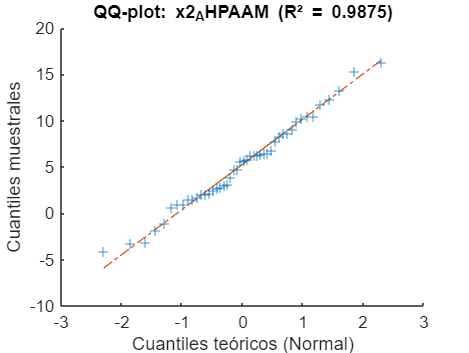

Variable "x2_AHPAAM": R² = 0.9875


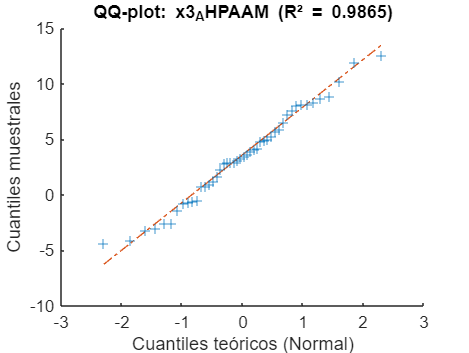

Variable "x3_AHPAAM": R² = 0.9865


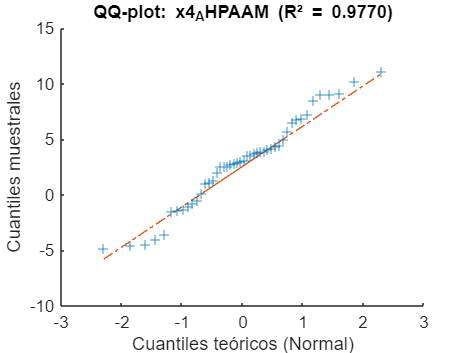

Variable "x4_AHPAAM": R² = 0.9770


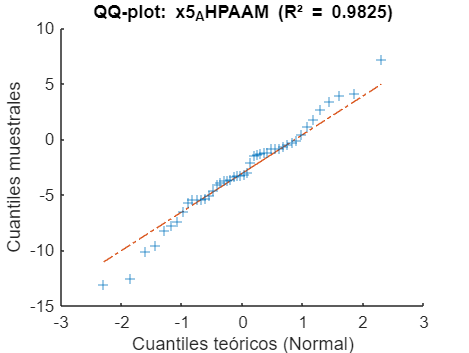

Variable "x5_AHPAAM": R² = 0.9825


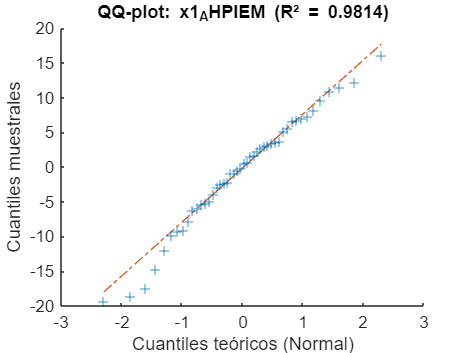

Variable "x1_AHPIEM": R² = 0.9814


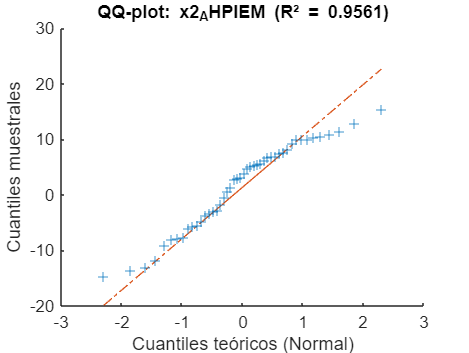

Variable "x2_AHPIEM": R² = 0.9561


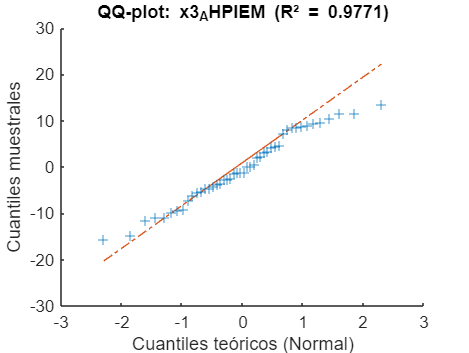

Variable "x3_AHPIEM": R² = 0.9771


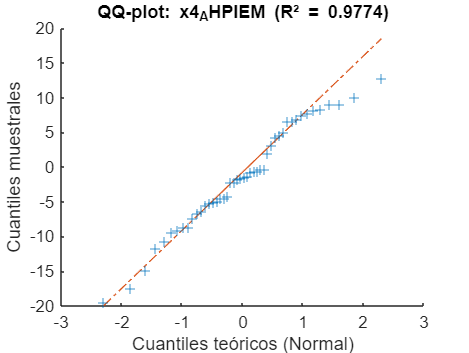

Variable "x4_AHPIEM": R² = 0.9774


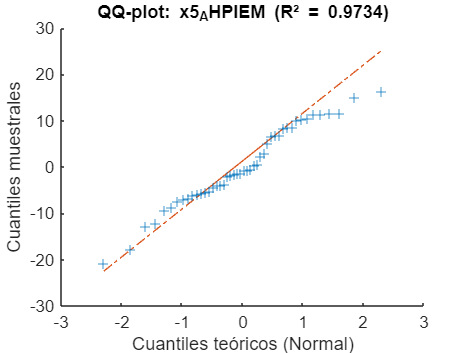

Variable "x5_AHPIEM": R² = 0.9734


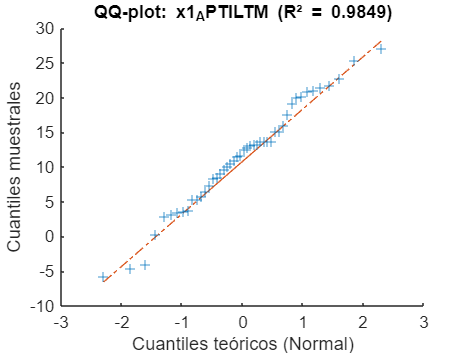

Variable "x1_APTILTM": R² = 0.9849


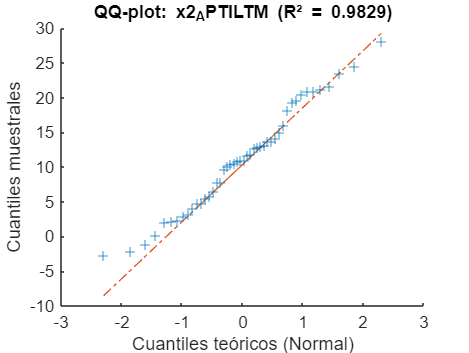

Variable "x2_APTILTM": R² = 0.9829


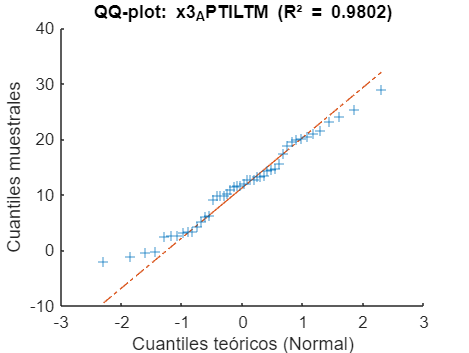

Variable "x3_APTILTM": R² = 0.9802


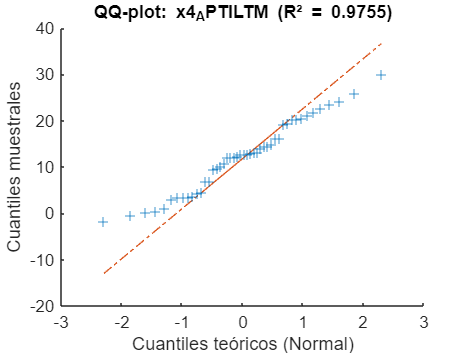

Variable "x4_APTILTM": R² = 0.9755


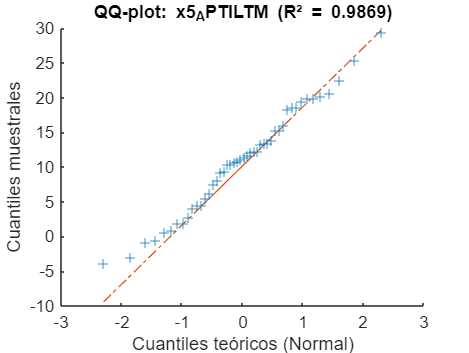

Variable "x5_APTILTM": R² = 0.9869


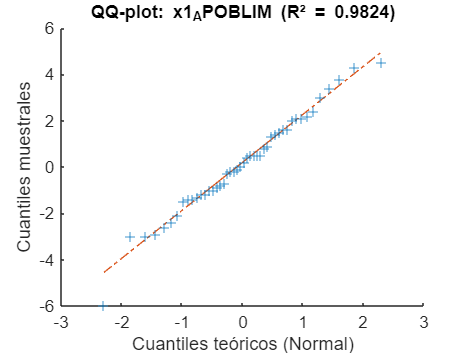

Variable "x1_APOBLIM": R² = 0.9824


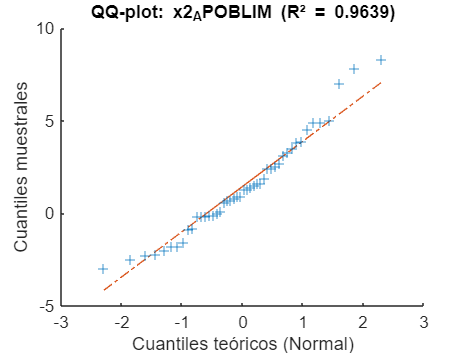

Variable "x2_APOBLIM": R² = 0.9639


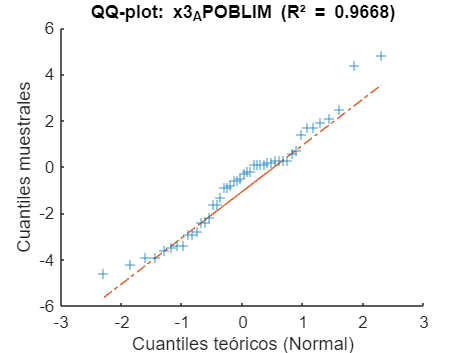

Variable "x3_APOBLIM": R² = 0.9668


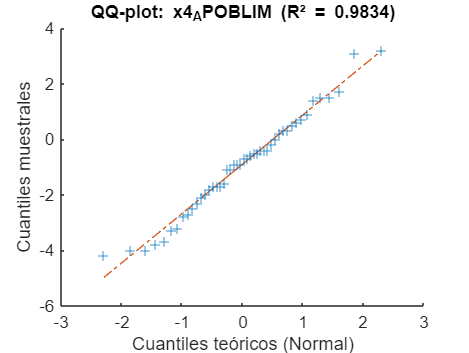

Variable "x4_APOBLIM": R² = 0.9834


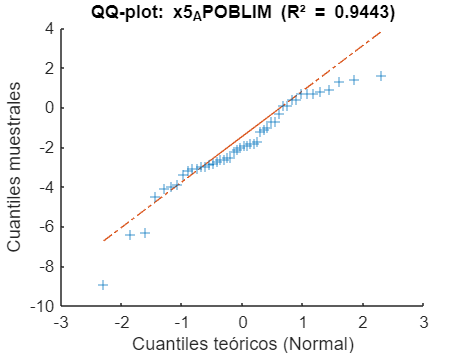

Variable "x5_APOBLIM": R² = 0.9443


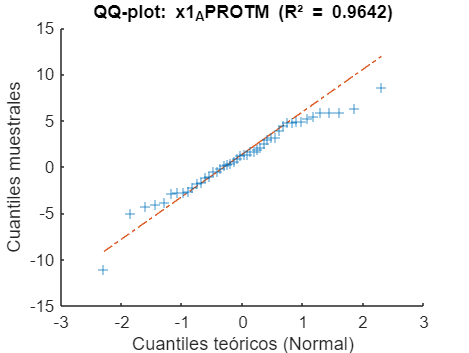

Variable "x1_APROTM": R² = 0.9642


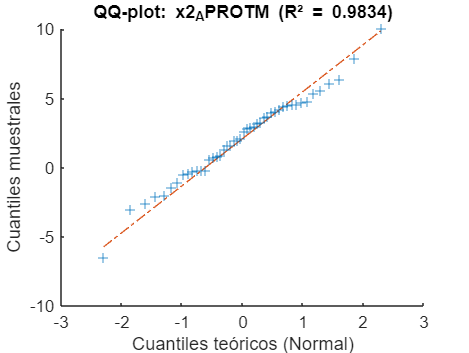

Variable "x2_APROTM": R² = 0.9834


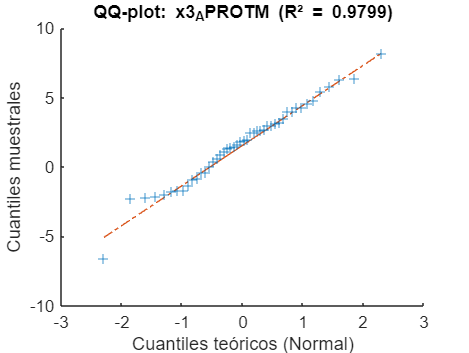

Variable "x3_APROTM": R² = 0.9799


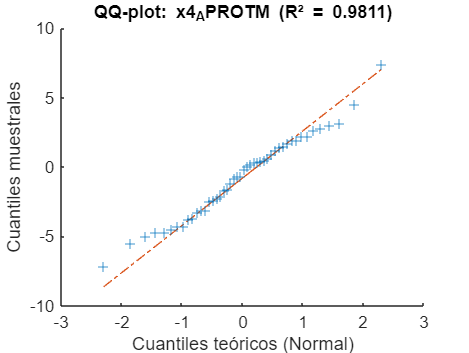

Variable "x4_APROTM": R² = 0.9811


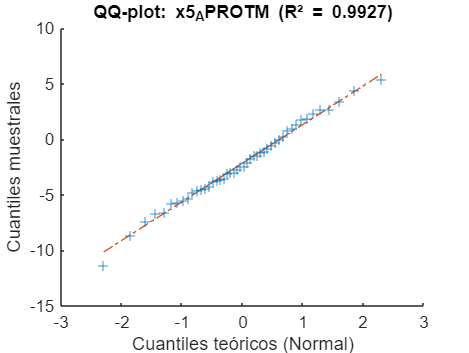

Variable "x5_APROTM": R² = 0.9927


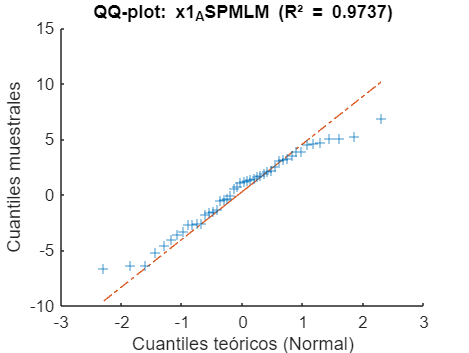

Variable "x1_ASPMLM": R² = 0.9737


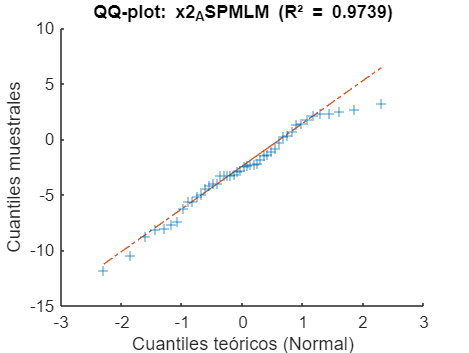

Variable "x2_ASPMLM": R² = 0.9739


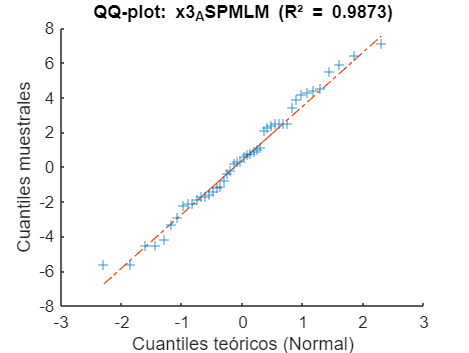

Variable "x3_ASPMLM": R² = 0.9873


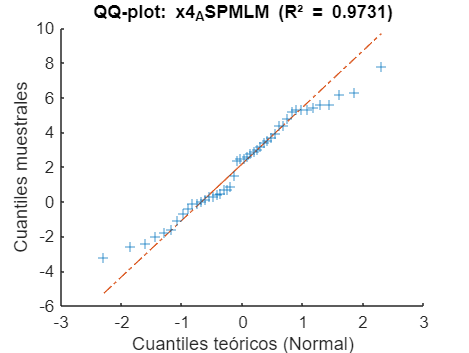

Variable "x4_ASPMLM": R² = 0.9731


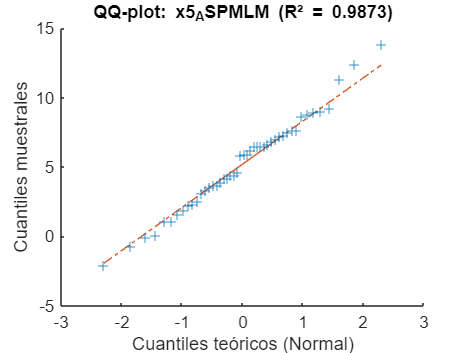

Variable "x5_ASPMLM": R² = 0.9873


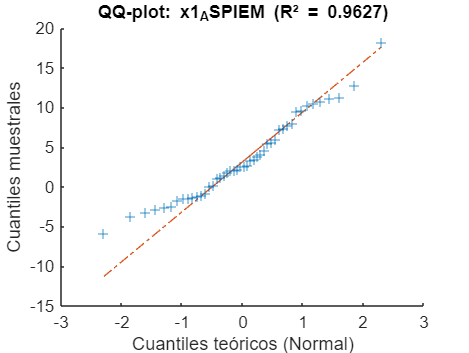

Variable "x1_ASPIEM": R² = 0.9627


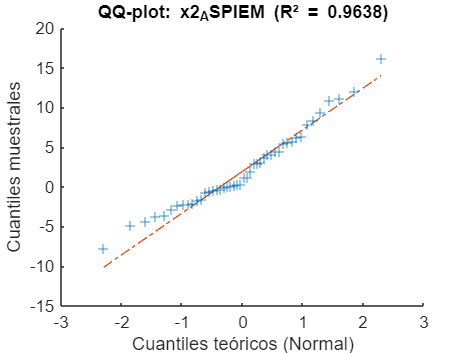

Variable "x2_ASPIEM": R² = 0.9638


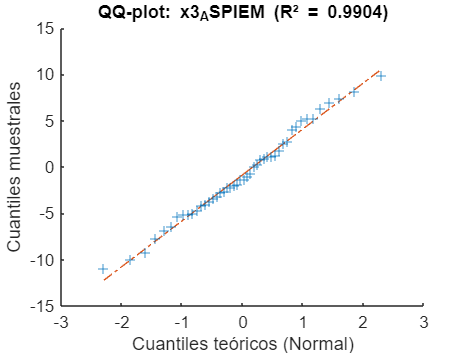

Variable "x3_ASPIEM": R² = 0.9904


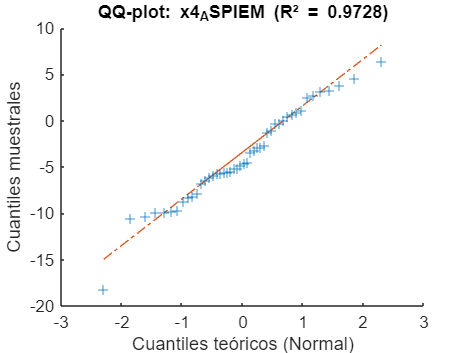

Variable "x4_ASPIEM": R² = 0.9728


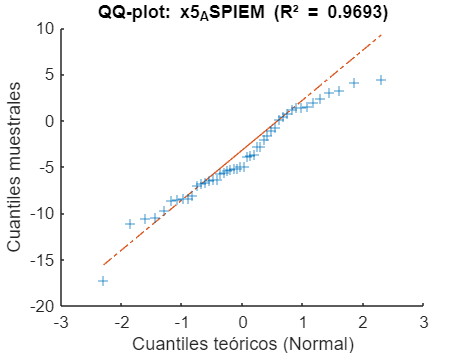

Variable "x5_ASPIEM": R² = 0.9693


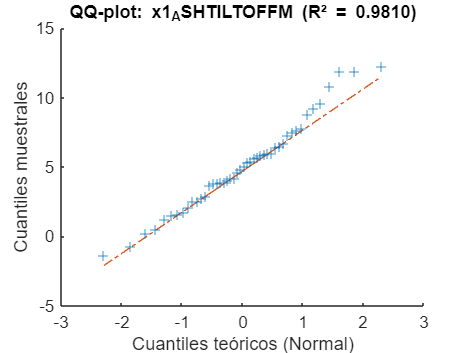

Variable "x1_ASHTILTOFFM": R² = 0.9810


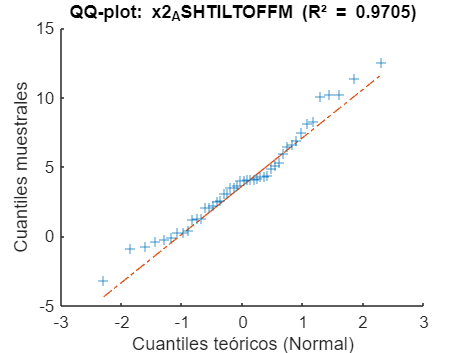

Variable "x2_ASHTILTOFFM": R² = 0.9705


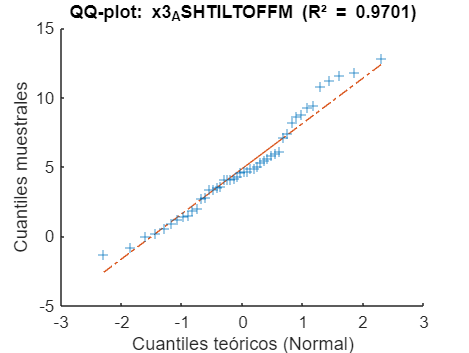

Variable "x3_ASHTILTOFFM": R² = 0.9701


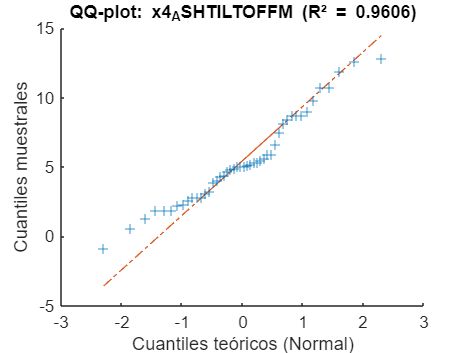

Variable "x4_ASHTILTOFFM": R² = 0.9606


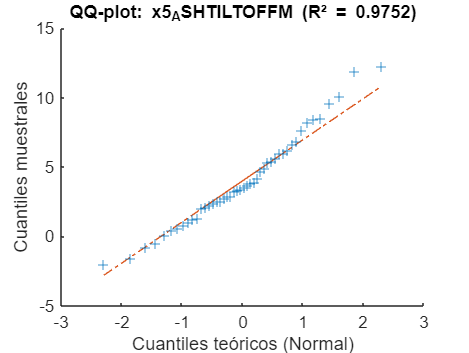

Variable "x5_ASHTILTOFFM": R² = 0.9752


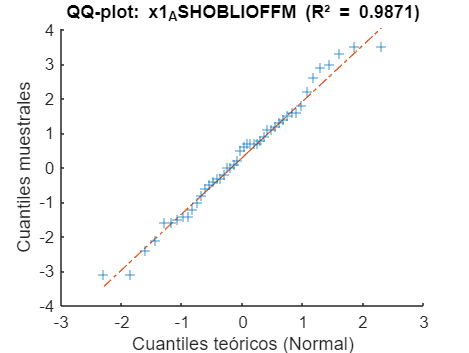

Variable "x1_ASHOBLIOFFM": R² = 0.9871


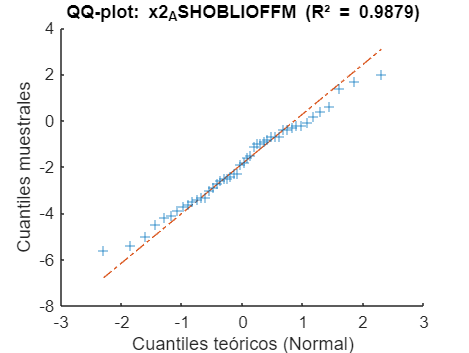

Variable "x2_ASHOBLIOFFM": R² = 0.9879


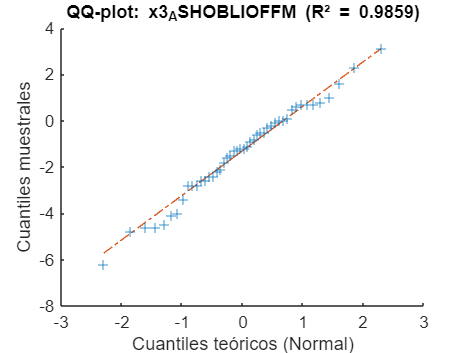

Variable "x3_ASHOBLIOFFM": R² = 0.9859


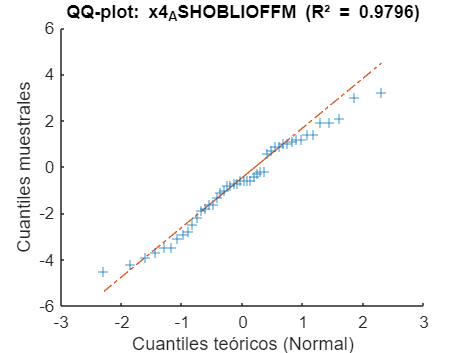

Variable "x4_ASHOBLIOFFM": R² = 0.9796


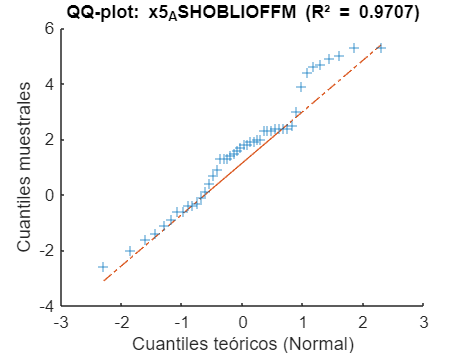

Variable "x5_ASHOBLIOFFM": R² = 0.9707


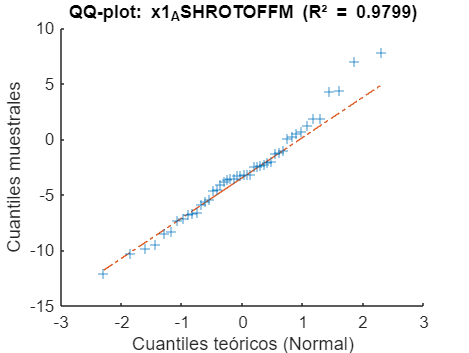

Variable "x1_ASHROTOFFM": R² = 0.9799


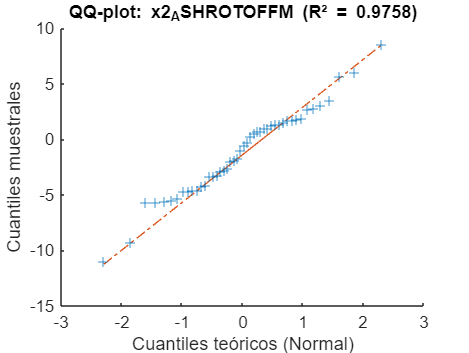

Variable "x2_ASHROTOFFM": R² = 0.9758


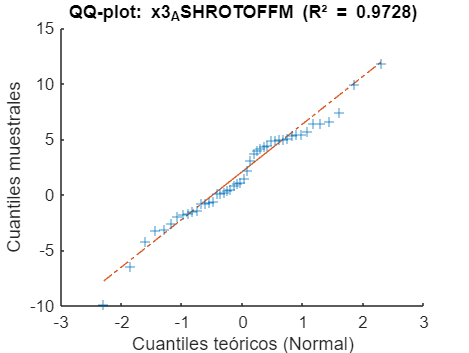

Variable "x3_ASHROTOFFM": R² = 0.9728


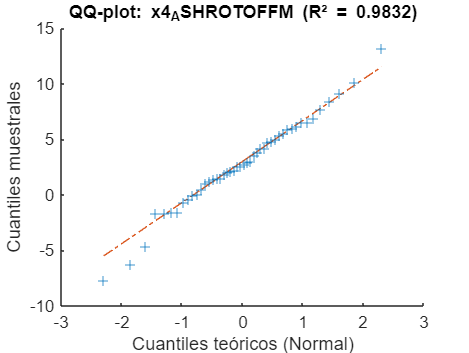

Variable "x4_ASHROTOFFM": R² = 0.9832


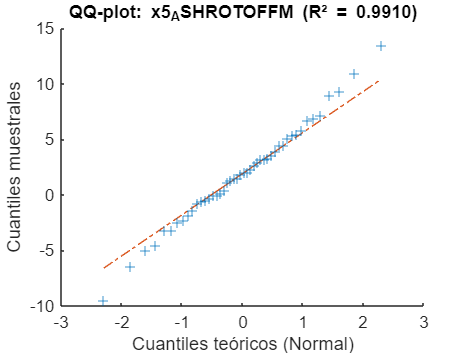

Variable "x5_ASHROTOFFM": R² = 0.9910


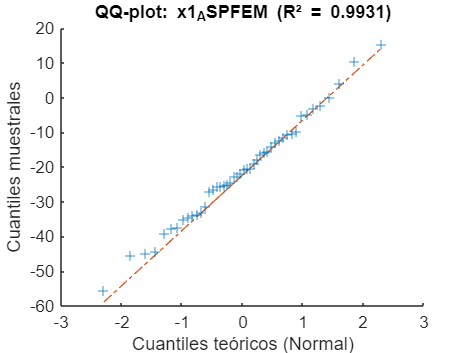

Variable "x1_ASPFEM": R² = 0.9931


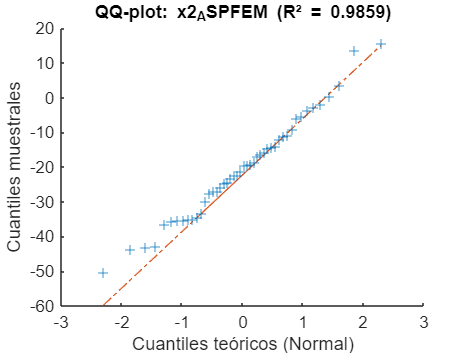

Variable "x2_ASPFEM": R² = 0.9859


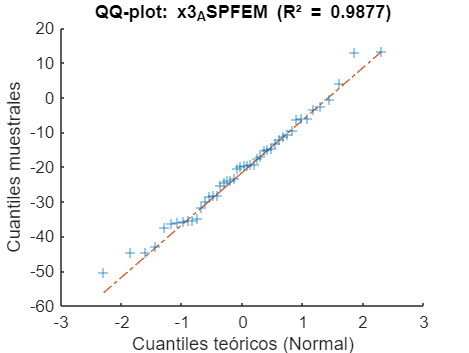

Variable "x3_ASPFEM": R² = 0.9877


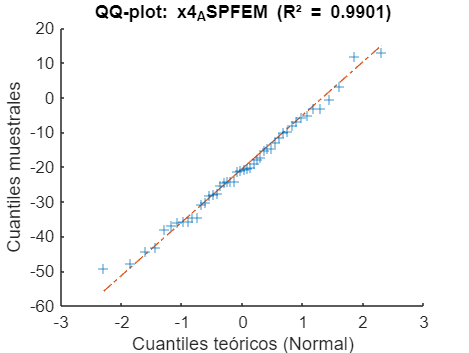

Variable "x4_ASPFEM": R² = 0.9901


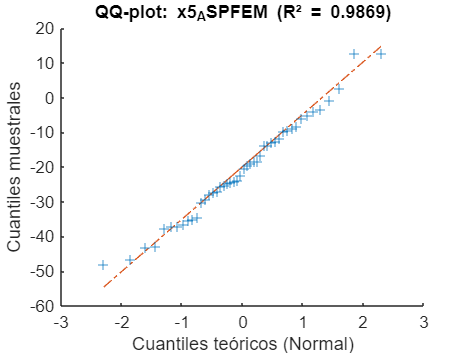

Variable "x5_ASPFEM": R² = 0.9869



for j = 3:p
    colData = X(:, j);
    varName = varNames{j};
    
    % Cuantiles teóricos normales
    sortedData = sort(colData);
    prob = ((1:n)' - 0.5) / n;
    theorQ = norminv(prob, mean(colData), std(colData));
    
    % Ajuste lineal para obtener R²
    lm = fitlm(theorQ, sortedData);
    R2 = lm.Rsquared.Ordinary;
    R2_values(j) = R2;
    
    % Mostrar QQ-plot
    figure;
    qqplot(colData);
    title(sprintf('QQ-plot: %s (R² = %.4f)', varName, R2));
    xlabel('Cuantiles teóricos (Normal)');
    ylabel('Cuantiles muestrales');
    
    % Mostrar por consola
    fprintf('Variable "%s": R² = %.4f\n', varName, R2);
end


% Crear tabla con nombres de variables y R²
R2_table = table(varNames(3:end)', R2_values(3:end), ...
    'VariableNames', {'Variable', 'R2'});

% Mostrar tabla completa y ordenada
disp('Tabla resumen de R² por variable:');

Tabla resumen de R² por variable:


disp(R2_table);

         Variable           R2   
    __________________    _______

    {'x1_AAFEM'      }    0.98527
    {'x2_AAFEM'      }    0.97074
    {'x3_AAFEM'      }    0.96282
    {'x4_AAFEM'      }    0.99198
    {'x5_AAFEM'      }    0.98196
    {'x1_AAIEM'      }    0.98219
    {'x2_AAIEM'      }    0.98669
    {'x3_AAIEM'      }     0.9868
    {'x4_AAIEM'      }    0.98934
    {'x5_AAIEM'      }     0.9802
    {'x1_AKFEM'      }     0.9527
    {'x2_AKFEM'      }    0.97671
    {'x3_AKFEM'      }    0.96975
    {'x4_AKFEM'      }    0.97333
    {'x5_AKFEM'      }    0.97239
    {'x1_AKAAM'      }    0.98344
    {'x2_AKAAM'      }    0.98661
    {'x3_AKAAM'      }    0.98216
    {'x4_AKAAM'      }    0.97623
    {'x5_AKAAM'      }    0.95663
    {'x1_AKIEM'      }    0.97734
    {'x2_AKIEM'      }    0.98306
    {'x3_AKIEM'      }    0.98655
    {'x4_AKIEM'      }    0.98835
    {'x5_AKIEM'      }    0.98025
    {'x1_AHPF


R2_table_sorted = sortrows(R2_table, 'R2', 'descend');
disp('Tabla ordenada por R² (descendente):');

Tabla ordenada por R² (descendente):


disp(R2_table_sorted);

         Variable           R2   
    __________________    _______

    {'x1_ASPFEM'     }    0.99308
    {'x5_APROTM'     }    0.99269
    {'x4_AAFEM'      }    0.99198
    {'x5_ASHROTOFFM' }    0.99103
    {'x3_ASPIEM'     }    0.99036
    {'x4_ASPFEM'     }    0.99014
    {'x4_AAIEM'      }    0.98934
    {'x4_AKIEM'      }    0.98835
    {'x2_ASHOBLIOFFM'}    0.98789
    {'x3_ASPFEM'     }    0.98769
    {'x2_AHPAAM'     }    0.98751
    {'x3_ASPMLM'     }    0.98733
    {'x5_ASPMLM'     }    0.98729
    {'x1_ASHOBLIOFFM'}    0.98713
    {'x5_ASPFEM'     }    0.98688
    {'x5_APTILTM'    }    0.98685
    {'x3_AAIEM'      }     0.9868
    {'x2_AAIEM'      }    0.98669
    {'x2_AKAAM'      }    0.98661
    {'x3_AKIEM'      }    0.98655
    {'x3_AHPAAM'     }    0.98652
    {'x3_ASHOBLIOFFM'}    0.98592
    {'x2_ASPFEM'     }    0.98587
    {'x1_AAFEM'      }    0.98527
    {'x1_APTILTM'    }    0.98492
    {'x1_AKAA

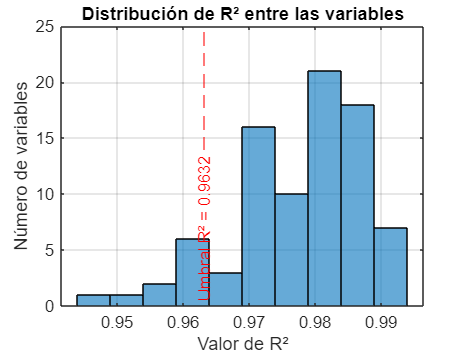


% Histograma de los valores de R²
R2_subset = R2_values(3:end);
figure;
histogram(R2_subset, 10);
xlabel('Valor de R²');
ylabel('Número de variables');
title('Distribución de R² entre las variables');
grid on;
hold on;
threshold = 0.9632;  % Umbral definido
xline(threshold, 'r--', 'Umbral R² = 0.9632', ...
      'LabelVerticalAlignment', 'bottom', 'LabelHorizontalAlignment', 'center');


% -------------------------------------------------------------------------
% Mostrar dos tablas: por encima y por debajo del umbral
% -------------------------------------------------------------------------
highIdx = R2_table.R2 >= threshold;
lowIdx  = R2_table.R2 <  threshold;

R2_above = R2_table(highIdx, :);
R2_below = R2_table(lowIdx,  :);

disp('Variables con R² >= 0.9632:');

Variables con R² >= 0.9671:


disp(R2_above);

         Variable           R2   
    __________________    _______

    {'x1_AAFEM'      }    0.98527
    {'x2_AAFEM'      }    0.97074
    {'x4_AAFEM'      }    0.99198
    {'x5_AAFEM'      }    0.98196
    {'x1_AAIEM'      }    0.98219
    {'x2_AAIEM'      }    0.98669
    {'x3_AAIEM'      }     0.9868
    {'x4_AAIEM'      }    0.98934
    {'x5_AAIEM'      }     0.9802
    {'x2_AKFEM'      }    0.97671
    {'x3_AKFEM'      }    0.96975
    {'x4_AKFEM'      }    0.97333
    {'x5_AKFEM'      }    0.97239
    {'x1_AKAAM'      }    0.98344
    {'x2_AKAAM'      }    0.98661
    {'x3_AKAAM'      }    0.98216
    {'x4_AKAAM'      }    0.97623
    {'x1_AKIEM'      }    0.97734
    {'x2_AKIEM'      }    0.98306
    {'x3_AKIEM'      }    0.98655
    {'x4_AKIEM'      }    0.98835
    {'x5_AKIEM'      }    0.98025
    {'x1_AHPFEM'     }    0.97106
    {'x2_AHPFEM'     }    0.97034
    {'x3_AHPFEM'     }    0.97456
    {'x4_AHPF


disp('Variables con R² < 0.9632:');

Variables con R² < 0.9671:


disp(R2_below);

         Variable           R2   
    __________________    _______

    {'x3_AAFEM'      }    0.96282
    {'x1_AKFEM'      }     0.9527
    {'x5_AKAAM'      }    0.95663
    {'x1_AHPAAM'     }    0.96317
    {'x2_AHPIEM'     }    0.95614
    {'x5_APOBLIM'    }    0.94435
    {'x1_ASPIEM'     }    0.96274
    {'x4_ASHTILTOFFM'}    0.96065



analizaremos los $r^2$, con $\alpha =0\ldotp 01$ y number of samples de 46 por lo tanto utilizaremos el valor como treshold 0.9632. Todo lo que este por debajo lo valoraremos como outlier.